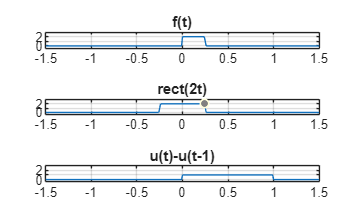

 %Input Function
f=@(t) 2*(rectangularPulse(2*t).*((t>=0 )-(t>=1)));
f1=@(t) 2*(rectangularPulse(2*t));
f2=@(t) ((t>=0)-(t>=1));
t=(-2:0.01:2);
tiledlayout(3,1);


%f(t)
ax1=nexttile;
plot(ax1,t,f(t));
title(ax1,"f(t)");
axis([-1.5 1.5 -0.5 3]);

%2rect(2t)
ax2 = nexttile;
plot(ax2, t, f1(t));
title(ax2, "rect(2t)");
axis([-1.5 1.5 -0.5 3]);

%u(t)-u(t-1)
ax3=nexttile;
plot(ax3,t,f2(t));
title(ax3,"u(t)-u(t-1)");
axis([-1.5 1.5 -0.5 3]);

% Add grid to each subplot for better visualization
grid(ax1);
grid(ax2);
grid(ax3);

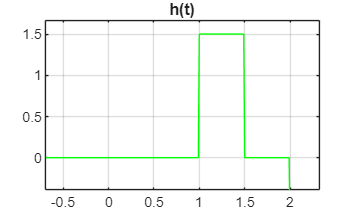


%system response
h=@(t) (1.5*((t>=1)-(t>=1.5)))-((t>=2)-(t>=2.5));
t=(-2:0.01:2);
tiledlayout(1,1)
plot(t,h(t),'g');
title("h(t)");
xlim([-0.69 2.32]);
ylim([-0.39 1.67]);
grid();

%direct convolution
t=(-2:0.01:2);
y=conv(f(t),h(t));


t =    -2.0000   -1.9900   -1.9800   -1.9700   -1.9600   -1.9500   -1.9400   -1.9300   -1.9200   -1.9100   -1.9000   -1.8900   -1.8800   -1.8700   -1.8600   -1.8500   -1.8400   -1.8300   -1.8200   -1.8100   -1.8000   -1.7900   -1.7800   -1.7700   -1.7600   -1.7500   -1.7400   -1.7300   -1.7200   -1.7100   -1.7000   -1.6900   -1.6800   -1.6700   -1.6600   -1.6500   -1.6400   -1.6300   -1.6200   -1.6100   -1.6000   -1.5900   -1.5800   -1.5700   -1.5600   -1.5500   -1.5400   -1.5300   -1.5200   -1.5100


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = -2

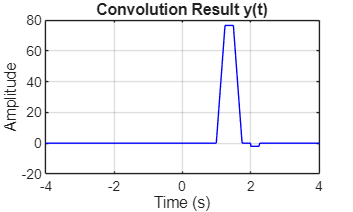

% Time vector for the convolution result
tConv = linspace(-4, 4, length(y)); 
% Plot the convolution result
figure;
plot(tConv, y, 'b');
title('Direct Convolution y(t)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

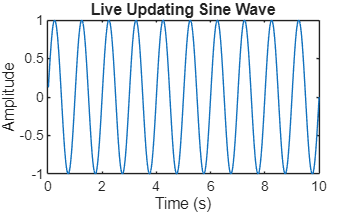

% Live updating sine wave plot
figure;
h = plot(NaN, NaN);   % Initialize empty plot
xlabel('Time (s)');
ylabel('Amplitude');
title('Live Updating Sine Wave');

% Parameters
Fs = 50;              % Sampling frequency
t = 0;                % Initial time
ydata = [];           % Store y values
xdata = [];           % Store x values

for k = 1:500
    % New data point
    t = t + 1/Fs;
    y = sin(2*pi*1*t);   % 1 Hz sine wave
    
    % Append data
    xdata(end+1) = t;
    ydata(end+1) = y;
    
    % Update plot
    set(h, 'XData', xdata, 'YData', ydata);
    drawnow;   % Refresh the figure
    
    pause(0.05); % Control update speed
end